# **RS-HL-15-6: Simulation 2 Cooperative**

**Hongseok Kim**

**UT Austin Oden Institute**

**07/20/24**

### **I. Load the Dataset**

% clear;clc;
% % Load the Satellite Contat Dataset
% addpath('~/Desktop/Redstone_Project/RS_HL/RS_HL_10_TV_MDP_Functions')
% load('~/RS_Dataset/RS_HL_3_dataset.mat')

### II. Destination Setting and Time Index Vector Setting

% time_index_vector = 100:130;
% start_time_index = 100:120;
% 
% % number_of_agents = 20;
% number_of_destinations = 4;
% state_vector = 1:48;
% 
% 
% % start_state = state_vector(randi(numel(state_vector), 1, number_of_agents));
% % destination_values = randsample(state_vector,number_of_destinations);
% % destination_state = destination_values(randi(numel(destination_values), 1, number_of_agents));
% % start_time = start_time_index(randi(numel(start_time_index), 1, number_of_agents));
% 
% 
% destination_values = [45, 2, 41, 32];
% % Destination State
% destination_state = [41, 45, 41, 45, 2, 45, 45, 32, 41, 2, 32, 45, 2, 2, 32, 32, 45, 2, 2, 41];
% 
% % Start Time
% start_time = [114, 115, 105, 114, 113, 103, 102, 110, 120, 107, 112, 104, 115, 105, 110, 114, 118, 120, 111, 102];
% 
% % Agents Input
% 
% start_state = [ 40, 44, 7, 44, 31, 5, 14, 27, 46, 47, 8, 47, 46, 24, 39, 7, 21, 44, 39, 47];

#### II.1 Run the MDP simulation for each destination

% 
% fprintf('Total Number of Destinations: %d\n', number_of_destinations);
% for destination_index = 1:number_of_destinations
%     fprintf('--------------------------------------\n')
%     fprintf('Running MDP %d / %d , Destination %d \n', destination_index,number_of_destinations,destination_values(destination_index));
%     MDP.(['MDP', num2str(destination_values(destination_index))]) = runMDP(sat_to_sat_contact_3d_matrix, time_index_vector,destination_values(destination_index));
% 
% end
%     fprintf('--------------------------------------\n')

### III. Configure each Agent's Setting

agents_input = [start_time', start_state', destination_state'];

### IV. Configure the simulation structure setting

% Level 1: Initialize simulation structure
sim = struct();

for time_index = time_index_vector
    sim.(['time' num2str(time_index)]) = {};
end

% Level 2/3: Initialize Agent (Level 2) with States and Destination (Level 3)

number_of_agents = length(agents_input(:,1));

for agent_index = 1:number_of_agents
   sim.(['time' num2str(agents_input(agent_index,1))]).(['agent' num2str(agent_index)]).('state') = agents_input(agent_index,2);
   sim.(['time' num2str(agents_input(agent_index,1))]).(['agent' num2str(agent_index)]).('destination') = agents_input(agent_index,3);   
end


### V. Propagation of agents' state

collision_flag = false;

for time_index = time_index_vector

    % If there's no active agent, continue to next time step
    if isempty(sim.(['time' num2str(time_index)]))
       continue;
    end


    % Parse the number of active agents
    number_of_active_agents = length(fieldnames(sim.(['time' num2str(time_index)])));

    % Make the status matrix represents current and next
    % [current_state, next_state, destination]
    status_matrix = zeros(3, number_of_active_agents);

    agents_list = fieldnames(sim.(['time' num2str(time_index)]));

    % Find the Next state from Current Agent-State 
    for active_agent_index = 1:number_of_active_agents
        % Find the Current State and Destination of given agent
        current_state = sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('state');
        destination = sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('destination');

        % Find the Next state from given MDP pi distribution
        pi_dist = MDP.(['MDP' num2str(destination)]).(['time' num2str(time_index)]).('policy_distribution');
        action_number = find(pi_dist(current_state,:) ~= 0);

        if length(action_number) > 1
        action_number = randsample(action_number,1);
        end

        next_state = MDP.(['MDP' num2str(destination)]).(['time' num2str(time_index)]).(['state' num2str(current_state)]).(['action' num2str(action_number)]).('success').('next_state');
        reward = MDP.(['MDP' num2str(destination)]).(['time' num2str(time_index)]).(['state' num2str(current_state)]).(['action' num2str(action_number)]).('success').('reward');
        state_value =  MDP.(['MDP' num2str(destination)]).(['time' num2str(time_index)]).(['state' num2str(current_state)]).('state_value');
        action_value  = MDP.(['MDP' num2str(destination)]).(['time' num2str(time_index)]).(['state' num2str(current_state)]).(['action' num2str(action_number)]).('action_value'); 

        % Configure Proposed status matrix for the collision test
        status_matrix(1,active_agent_index) = current_state;
        status_matrix(2,active_agent_index) = next_state;
        status_matrix(3,active_agent_index) = destination;

        % Add State Value
        sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('state_value') = state_value;

        % Save the Original Reward and action value to prepare the update
        sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('original_action_number') = action_number;
        sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('original_action_value') = action_value;
        sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('original_reward') = reward;

        % Add the action number, reward, action value (may be changed)
        sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('action_number') = action_number;        
        sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('action_value') = action_value;
        sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('reward') = reward;
    end


    % Break when time index reaches the end time
    if time_index == max(time_index_vector)
       break;
    end

    for active_agent_index = 1:number_of_active_agents

        % Don't update the agent already arrived to destination
        if status_matrix(1,active_agent_index) ==  status_matrix(3,active_agent_index)
            continue;
        end

        % Update the time+1 for next state
        sim.(['time' num2str(time_index+1)]).(agents_list{active_agent_index}).('state') = status_matrix(2,active_agent_index);
        sim.(['time' num2str(time_index+1)]).(agents_list{active_agent_index}).('destination') = status_matrix(3,active_agent_index);       
    end


    % Avoid Collision Avoidance Algorithm


    % If next state Agent info is empty, continue
    if isempty(sim.(['time' num2str(time_index+1)]))
        continue;
    end

    % Parse the number of next state active agents
    next_state_number_of_active_agents = length(fieldnames(sim.(['time' num2str(time_index+1)])));
    next_state_status_matrix = zeros(1, next_state_number_of_active_agents);
    next_state_agents_list = fieldnames(sim.(['time' num2str(time_index+1)]));

    for next_state_agent_index = 1:next_state_number_of_active_agents
        next_state_status_matrix(next_state_agent_index) = sim.(['time' num2str(time_index+1)]).(next_state_agents_list{next_state_agent_index}).('state');
    end

    unique_elements = unique(next_state_status_matrix);

    % If there is no collision -> contintue
    if length(next_state_status_matrix) == length(unique_elements)
        continue;
    end

### VI. If there exists Collision -> Activate Collision Avoidance Algorithm

    fprintf('--------------------------------------\n')
    fprintf('collision occured at time index %d\n', time_index);
    % If there exist collision -> Start the infinite loop until the
    % problem resolved
    collision_flag = true;


    while collision_flag == true
     % Collect Action value vector of each agent's state

     action_value_struct = struct();
     vector_length_information = zeros(number_of_active_agents,1);

     for active_agent_index = 1:number_of_active_agents
        % Find the Current State and Destination of given agent
        current_state = sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('state');
        destination = sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('destination');

        % Get the Action value Matrix from given state in given MDP
        action_value_vector = MDP.(['MDP' num2str(destination)]).(['time' num2str(time_index)]).(['state' num2str(current_state)]).('action_value_vector');       
        vector_length = length(action_value_vector);
        action_value_matrix = [(1:vector_length)',action_value_vector];
        action_value_matrix = sortrows(action_value_matrix,2, 'descend');

        if vector_length > 4
            action_value_matrix = action_value_matrix(1:4,:);
        end

        action_value_struct.(agents_list{active_agent_index}).('action_value_matrix') = action_value_matrix;
        vector_length_information(active_agent_index) = length(action_value_matrix(:,1));
     end


     % Generate Cases For Each Action Value
     combination_matrix = [];

     if number_of_active_agents == 1
        combination_matrix = (1:vector_length_information(active_agent_index))';
     else


         for active_agent_index = 1:number_of_active_agents-1
            new_matrix = [];
            if active_agent_index == 1
               pre_matrix = (1:vector_length_information(active_agent_index))';
            else
               pre_matrix = combination_matrix;
            end

            length_of_pre_matrix = length(pre_matrix(:,1));

            for next_agent_index = 1:vector_length_information(active_agent_index+1)

            adding_vector = ones(length_of_pre_matrix,1)*next_agent_index;
            new_matrix_segment = [pre_matrix,adding_vector];
            new_matrix = [new_matrix;new_matrix_segment];

            end
            combination_matrix = new_matrix;
         end
     end
     fprintf('No. of Active Agents: %d, No. of Agent-Action Cases: %d \n', number_of_active_agents, length(combination_matrix(:,1)));

     if number_of_active_agents == 1
        combination_matrix =  (1:vector_length_information(1))';
     end

     action_number_matrix = zeros(length(combination_matrix(:,1)),number_of_active_agents);
     action_value_matrix = zeros(length(combination_matrix(:,1)),number_of_active_agents);
     action_value_sum_vector = zeros(length(combination_matrix(:,1)),1);
     next_state_matrix =  zeros(length(combination_matrix(:,1)),number_of_active_agents);




     for case_index = 1:length(combination_matrix(:,1))
         for active_agent_index = 1:number_of_active_agents
             action_index = combination_matrix(case_index,active_agent_index);

             action_value_info =  action_value_struct.(agents_list{active_agent_index}).('action_value_matrix');

             action_number = action_value_info(action_index,1);
             action_value = action_value_info(action_index,2);

             action_number_matrix(case_index,active_agent_index) = action_number;
             action_value_matrix(case_index,active_agent_index) = action_value;


             current_state = sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('state');
             destination = sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('destination');


             next_state_info =  MDP.(['MDP' num2str(destination)]).(['time' num2str(time_index)]).(['state' num2str(current_state)]).(['action' num2str(action_number)]).('success').('next_state');
             next_state_matrix(case_index,active_agent_index) = next_state_info;

         end
         action_value_sum_vector(case_index) = sum(action_value_matrix(case_index,:));
     end

     case_evaluation_matrix = [next_state_matrix,action_number_matrix,action_value_sum_vector];
     case_evaluation_matrix = sortrows(case_evaluation_matrix,length(case_evaluation_matrix(1,:)), 'descend');
     action_value_sorted_matrix = [action_value_matrix,action_value_sum_vector];
     action_value_sorted_matrix = sortrows(action_value_sorted_matrix, length(action_value_sorted_matrix(1,:)),'descend');

     optimal_action_values = action_value_sorted_matrix(1,:);
     fprintf('Optimal Action Values: ')
     for i = 1:length(optimal_action_values)
        if i == length(optimal_action_values)
            fprintf('Sum: %4.2f ', optimal_action_values(i));
        else
            fprintf('%4.2f ', optimal_action_values(i));
        end

     end

     for  case_index = 1:length(combination_matrix(:,1))

        next_state = case_evaluation_matrix(case_index,1:number_of_active_agents); 
        % Modify Status Matrix for corresponding next state vector
        status_matrix(2,:) = next_state;

        for active_agent_index = 1:number_of_active_agents

            % Don't update the agent already arrived to destination
            if status_matrix(1,active_agent_index) ==  status_matrix(3,active_agent_index)
                continue;
            end

            % Update states the time+1 for next state
            sim.(['time' num2str(time_index+1)]).(agents_list{active_agent_index}).('state') = status_matrix(2,active_agent_index);
        end

        % Parse the number of next state active agents
        next_state_number_of_active_agents = length(fieldnames(sim.(['time' num2str(time_index+1)])));
        next_state_status_matrix = zeros(1, next_state_number_of_active_agents);

        for next_state_agent_index = 1:next_state_number_of_active_agents
            next_state_status_matrix(next_state_agent_index) = sim.(['time' num2str(time_index+1)]).(next_state_agents_list{next_state_agent_index}).('state');
        end

        unique_elements = unique(next_state_status_matrix);

        % If there is no collision -> continue
        if length(next_state_status_matrix) == length(unique_elements)
            selected_action_number_vector = case_evaluation_matrix(case_index,number_of_active_agents+1:2*number_of_active_agents);


           for active_agent_index = 1:number_of_active_agents

            action_number = selected_action_number_vector(active_agent_index);
            action_value = action_value_sorted_matrix(case_index,active_agent_index);

            % Parse the updated reward, state value and action value
            current_state = sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('state');
            destination = sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('destination');
            reward = MDP.(['MDP' num2str(destination)]).(['time' num2str(time_index)]).(['state' num2str(current_state)]).(['action' num2str(action_number)]).('success').('reward');



            % Modify the reward, state value and action value
            sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('reward') = reward;
            sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('action_number') = action_number;
            sim.(['time' num2str(time_index)]).(agents_list{active_agent_index}).('action_value') = action_value;

           end


           updated_action_values = action_value_sorted_matrix(case_index,:);
           fprintf('Updated Action Values at case index %d: \n', case_index);
           for i = 1:length(updated_action_values)
                if i == length(updated_action_values)
                     fprintf('Sum: %4.2f ', updated_action_values(i));
                else
                     fprintf('%4.2f ', updated_action_values(i));
                end
           end
           fprintf('Collision Resolved! \n')


           fprintf('  \n')
           collision_flag = false;  
           break;
        end

     end


     if collision_flag == true
         fprintf('we could not resolve the collision at time index %d\n', time_index);
            break;
     end

    end

    if collision_flag == true

    fprintf('Simulation Ended with fail');
    break;
    end
end

--------------------------------------


collision occured at time index 110


No. of Active Agents: 3, No. of Agent-Action Cases: 64 


Optimal Action Values: 

96.00 94.00 97.00 

Sum: 287.00 

Updated Action Values at case index 3: 


96.00 92.00 97.00 

Sum: 285.00 

Collision Resolved! 


--------------------------------------


collision occured at time index 111


No. of Active Agents: 4, No. of Agent-Action Cases: 256 


Optimal Action Values: 

78.00 97.00 93.00 98.00 

Sum: 366.00 

Updated Action Values at case index 4: 


78.00 97.00 91.00 98.00 

Sum: 364.00 

Collision Resolved! 


--------------------------------------


collision occured at time index 112


No. of Active Agents: 5, No. of Agent-Action Cases: 1024 


Optimal Action Values: 

85.00 79.00 98.00 92.00 99.00 

Sum: 453.00 

Updated Action Values at case index 10: 


85.00 79.00 98.00 90.00 99.00 

Sum: 451.00 

Collision Resolved! 


--------------------------------------


collision occured at time index 113


No. of Active Agents: 6, No. of Agent-Action Cases: 4096 


Optimal Action Values: 

83.00 100.00 80.00 99.00 91.00 100.00 

Sum: 553.00 

Updated Action Values at case index 11: 


83.00 100.00 80.00 99.00 89.00 100.00 

Sum: 551.00 

Collision Resolved! 


--------------------------------------


collision occured at time index 116


No. of Active Agents: 6, No. of Agent-Action Cases: 256 


Optimal Action Values: 

0.00 100.00 0.00 100.00 83.00 92.00 

Sum: 375.00 

Updated Action Values at case index 2: 


0.00 100.00 0.00 98.00 83.00 92.00 

Sum: 373.00 

Collision Resolved! 


--------------------------------------


collision occured at time index 120


No. of Active Agents: 5, No. of Agent-Action Cases: 64 


Optimal Action Values: 

96.00 83.00 0.00 0.00 96.00 

Sum: 275.00 

Updated Action Values at case index 2: 


94.00 83.00 0.00 0.00 96.00 

Sum: 273.00 

Collision Resolved! 


--------------------------------------


collision occured at time index 121


No. of Active Agents: 3, No. of Agent-Action Cases: 64 


Optimal Action Values: 

95.00 84.00 97.00 

Sum: 276.00 

Updated Action Values at case index 2: 


93.00 84.00 97.00 

Sum: 274.00 

Collision Resolved! 



if collision_flag == false
fprintf('Simulation Ended with Success')
end

Simulation Ended with Success

### VI. result display

result_matrix = zeros(length(time_index_vector),number_of_agents);
reward_matrix =  zeros(length(time_index_vector),number_of_agents);
state_value_matrix = zeros(length(time_index_vector),number_of_agents);
action_value_matrix = zeros(length(time_index_vector),number_of_agents);
cumulative_reward_matrix = zeros(length(time_index_vector),number_of_agents);

for time_index = time_index_vector

    if isempty(sim.(['time' num2str(time_index)]))
     continue;
    end

    agents_list = fieldnames(sim.(['time' num2str(time_index)]));
    number_of_agents = length(agents_list);

    for agent_index = 1:number_of_agents
        agent_name = cell2mat(agents_list(agent_index));
        agent_no = regexp(agent_name, '\d+','match');
        agent_number = str2double(agent_no{1});

        result_matrix(time_index - min(time_index_vector) + 1,agent_number) = sim.(['time' num2str(time_index)]).(agent_name).('state');
        reward_matrix(time_index - min(time_index_vector) + 1,agent_number) =  sim.(['time' num2str(time_index)]).(agent_name).('reward');
        state_value_matrix(time_index - min(time_index_vector) + 1,agent_number) = sim.(['time' num2str(time_index)]).(agent_name).('state_value');
        action_value_matrix(time_index - min(time_index_vector) + 1,agent_number) = sim.(['time' num2str(time_index)]).(agent_name).('action_value');
        cumulative_reward_matrix(time_index - min(time_index_vector) + 1,agent_number) = sum(reward_matrix(1:time_index - min(time_index_vector) + 1,agent_number));

    end

end

result = [time_index_vector' , result_matrix]

result =    100     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   101     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   102     0     0     0     0     0     0    14     0     0     0     0     0     0     0     0     0     0     0     0    47
   103     0     0     0     0     0     5    15     0     0     0     0     0     0     0     0     0     0     0     0    46
   104     0     0     0     0     0     4    16     0     0     0     0    47     0     0     0     0     0     0     0    45
   105     0     0     7     0     0     3    17     0     0     0     0    46     0    24     0     0     0     0     0    44
   106     0     0    33     0     0     2    18     0     0     0     0    45     0     1     0     0     0     0     0    43
   107     0     0    34     0     0     1    44     0     0    47     0     0     0     2     0     0

reward = [time_index_vector', reward_matrix]

reward =    100     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   101     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   102     0     0     0     0     0     0    -1     0     0     0     0     0     0     0     0     0     0     0     0    -1
   103     0     0     0     0     0    -1    -1     0     0     0     0     0     0     0     0     0     0     0     0    -1
   104     0     0     0     0     0    -1    -1     0     0     0     0    -1     0     0     0     0     0     0     0    -1
   105     0     0   -15     0     0    -1    -1     0     0     0     0   100     0   -15     0     0     0     0     0    -1
   106     0     0    -1     0     0    -1   -15     0     0     0     0     0     0   100     0     0     0     0     0    -1
   107     0     0    -1     0     0   -15   100     0     0   -15     0     0     0     0     0     0

cumulative_reward = [time_index_vector', cumulative_reward_matrix]

cumulative_reward =    100     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   101     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   102     0     0     0     0     0     0    -1     0     0     0     0     0     0     0     0     0     0     0     0    -1
   103     0     0     0     0     0    -1    -2     0     0     0     0     0     0     0     0     0     0     0     0    -2
   104     0     0     0     0     0    -2    -3     0     0     0     0    -1     0     0     0     0     0     0     0    -3
   105     0     0   -15     0     0    -3    -4     0     0     0     0    99     0   -15     0     0     0     0     0    -4
   106     0     0   -16     0     0    -4   -19     0     0     0     0    99     0    85     0     0     0     0     0    -5
   107     0     0   -17     0     0   -19    81     0     0   -15     0     0     0    85 

state_value = [time_index_vector', state_value_matrix]

state_value =    100     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   101     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   102     0     0     0     0     0     0    81     0     0     0     0     0     0     0     0     0     0     0     0    95
   103     0     0     0     0     0    81    82     0     0     0     0     0     0     0     0     0     0     0     0    96
   104     0     0     0     0     0    82    83     0     0     0     0    99     0     0     0     0     0     0     0    97
   105     0     0    78     0     0    83    84     0     0     0     0   100     0    85     0     0     0     0     0    98
   106     0     0    93     0     0    84    85     0     0     0     0     0     0   100     0     0     0     0     0    99
   107     0     0    94     0     0    85   100     0     0    85     0     0     0     0     0 

action_value = [time_index_vector', action_value_matrix]

action_value =    100     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   101     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
   102     0     0     0     0     0     0    81     0     0     0     0     0     0     0     0     0     0     0     0    95
   103     0     0     0     0     0    81    82     0     0     0     0     0     0     0     0     0     0     0     0    96
   104     0     0     0     0     0    82    83     0     0     0     0    99     0     0     0     0     0     0     0    97
   105     0     0    78     0     0    83    84     0     0     0     0   100     0    85     0     0     0     0     0    98
   106     0     0    93     0     0    84    85     0     0     0     0     0     0   100     0     0     0     0     0    99
   107     0     0    94     0     0    85   100     0     0    85     0     0     0     0     0

### VII. Result Graph

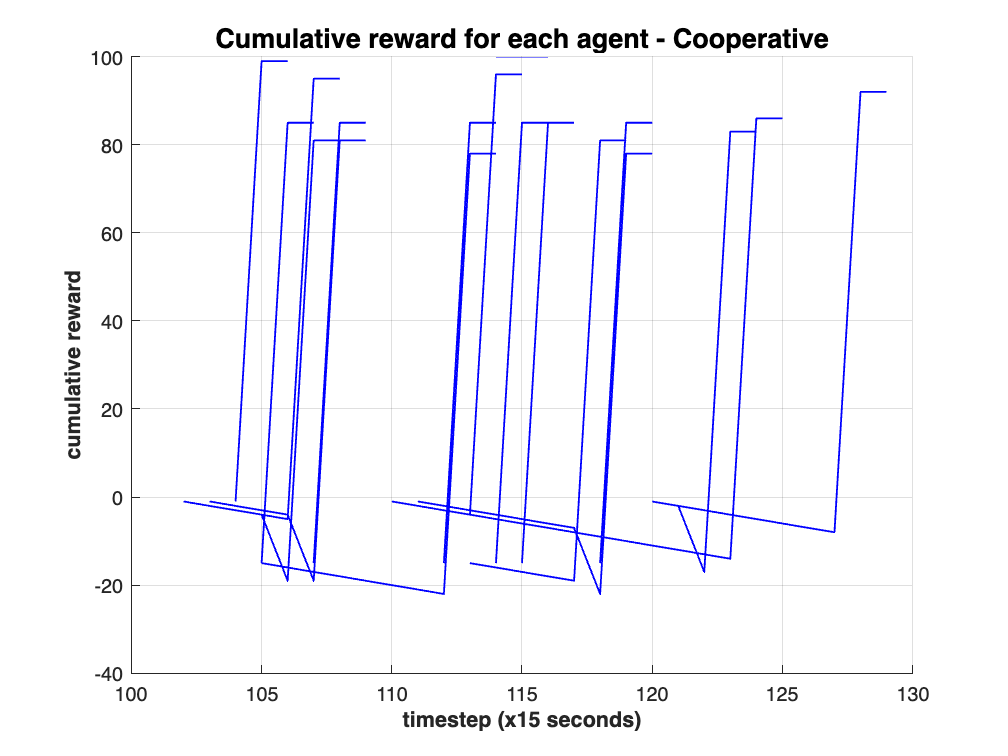

number_of_agents = length(agents_input(:,1));

figure;
hold on
for agent_index = 1:number_of_agents

    cumulative_reward_each_agent = [time_index_vector', cumulative_reward_matrix(:,agent_index)];
    cumulative_reward_each_agent = cumulative_reward_each_agent(cumulative_reward_each_agent(:,2) ~= 0, :);
    
   plot(cumulative_reward_each_agent(:,1),cumulative_reward_each_agent(:,2),'Color','b','LineWidth',1)  
end
hold off
grid on
title('Cumulative reward for each agent - Cooperative','FontSize',15,'FontWeight','bold')
xlabel('timestep (x15 seconds)','FontSize',12,'FontWeight','bold')
ylabel('cumulative reward','FontSize',12,'FontWeight','bold')

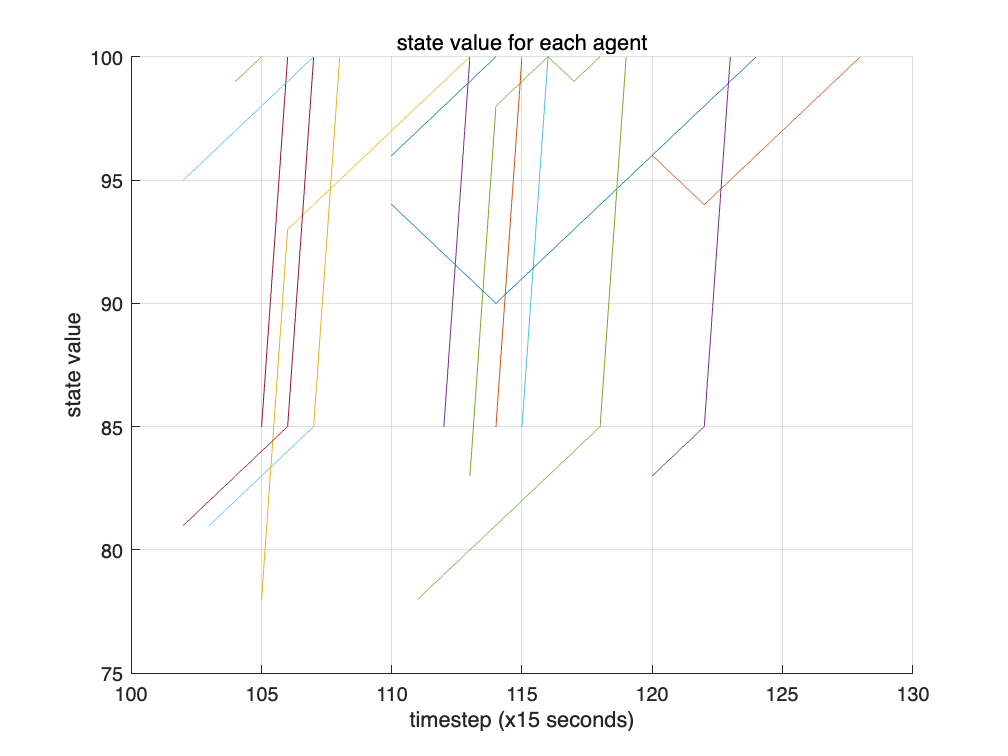


figure;
hold on
for agent_index = 1:number_of_agents

    state_value_each_agent = [time_index_vector', state_value_matrix(:,agent_index)];
    state_value_each_agent = state_value_each_agent(state_value_each_agent(:,2) ~= 0, :);

    plot(state_value_each_agent(:,1),state_value_each_agent(:,2))
end
hold off
grid on
title('state value for each agent')
xlabel('timestep (x15 seconds)')
ylabel('state value')

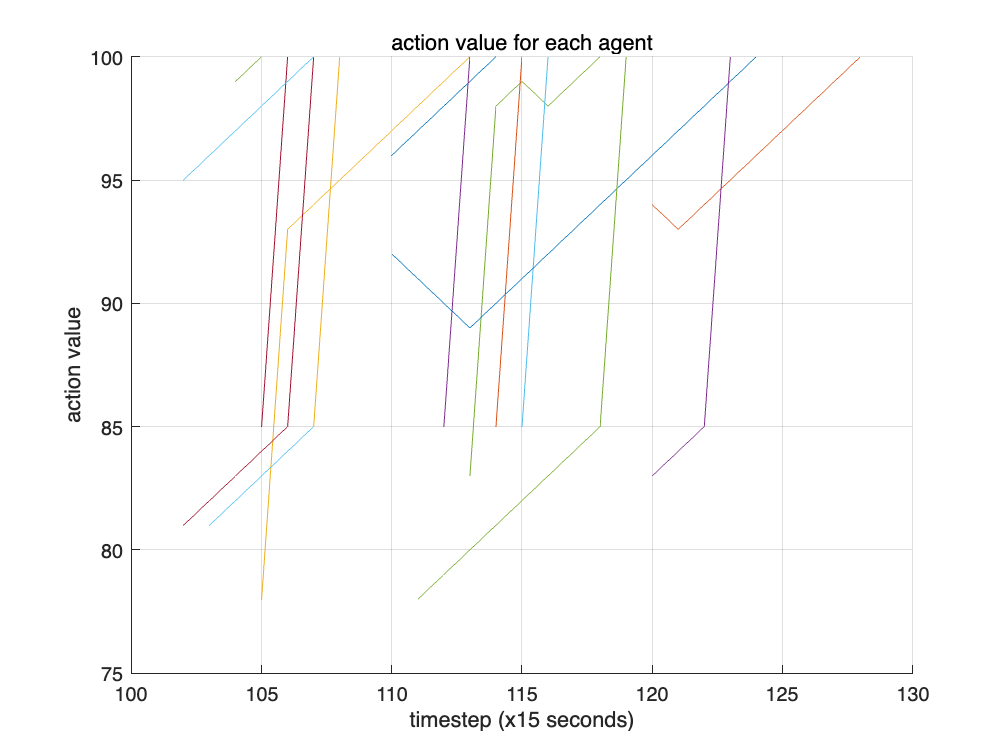


figure;
hold on
for agent_index = 1:number_of_agents

    action_value_each_agent = [time_index_vector', action_value_matrix(:,agent_index)];
    action_value_each_agent = action_value_each_agent(action_value_each_agent(:,2) ~= 0, :);
    plot(action_value_each_agent(:,1),action_value_each_agent(:,2))
end
hold off
grid on
title('action value for each agent')
xlabel('timestep (x15 seconds)')
ylabel('action value')

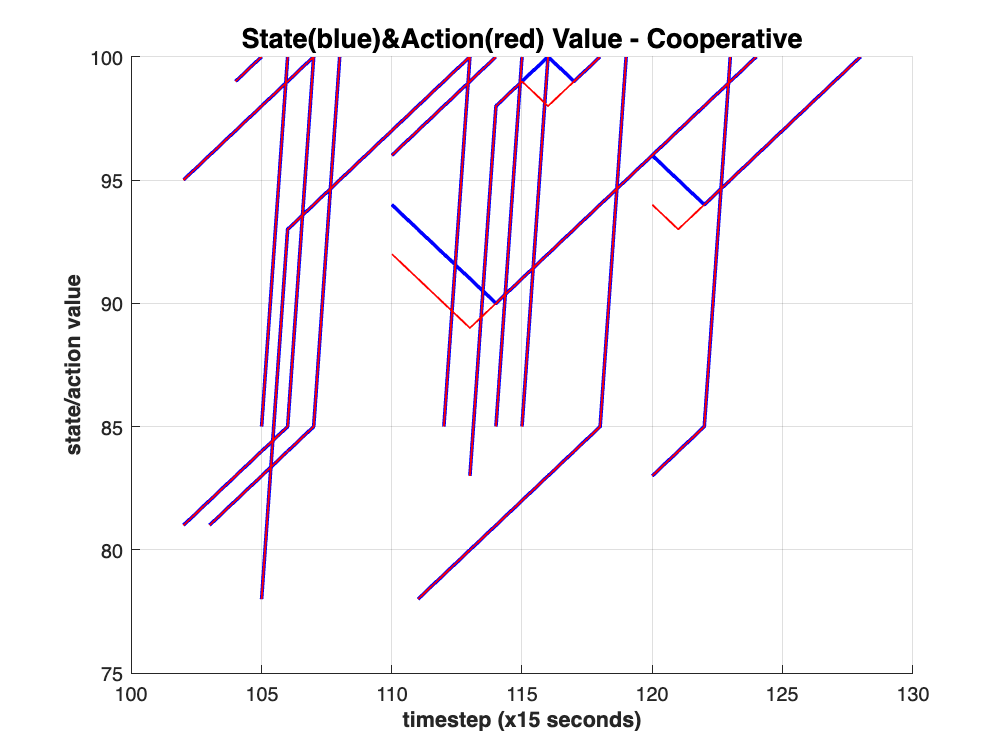




figure;
hold on
for agent_index = 1:number_of_agents

    state_value_each_agent = [time_index_vector', state_value_matrix(:,agent_index)];
    state_value_each_agent = state_value_each_agent(state_value_each_agent(:,2) ~= 0, :);

    plot(state_value_each_agent(:,1),state_value_each_agent(:,2),'b','LineWidth',2)
end


for agent_index = 1:number_of_agents

    action_value_each_agent = [time_index_vector', action_value_matrix(:,agent_index)];
    action_value_each_agent = action_value_each_agent(action_value_each_agent(:,2) ~= 0, :);
    plot(action_value_each_agent(:,1),action_value_each_agent(:,2),'r','LineWidth',1)
end
hold off
grid on
title('State(blue)&Action(red) Value - Cooperative','FontSize',15,'FontWeight','bold')
xlabel('timestep (x15 seconds)','FontSize',12,'FontWeight','bold')
ylabel('state/action value','FontSize',12,'FontWeight','bold')

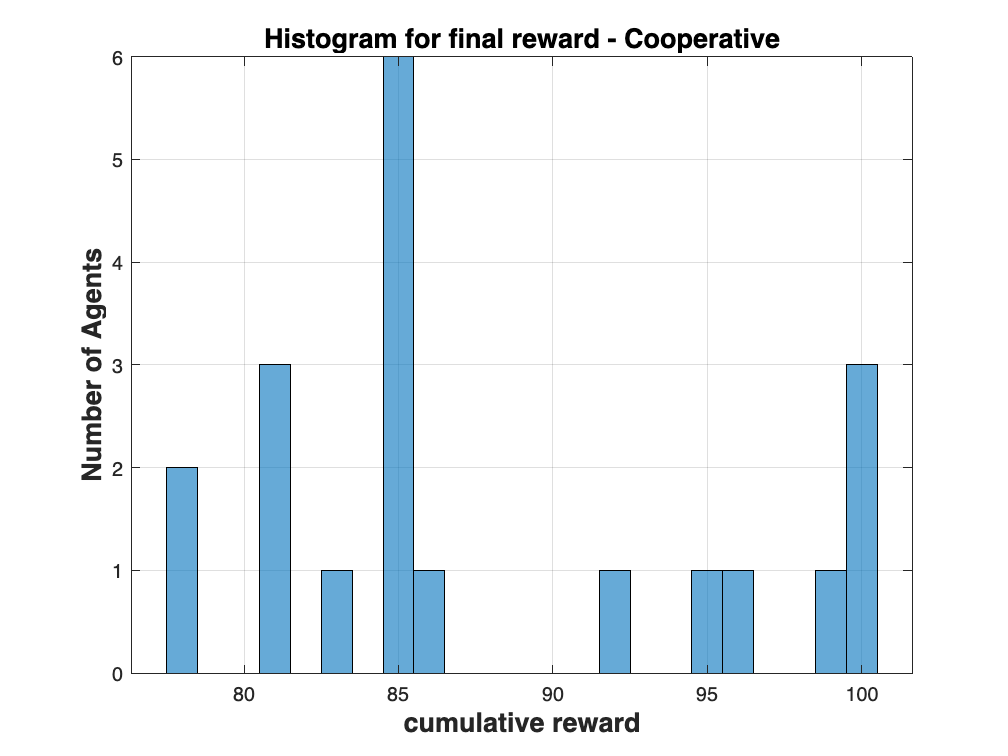




final_cumulative_reward_vector = zeros(number_of_agents,1);
for agent_index = 1:number_of_agents
    each_agent_reward_vector = cumulative_reward_matrix(:,agent_index);
    each_agent_reward= each_agent_reward_vector(each_agent_reward_vector ~= 0);
    if isempty(each_agent_reward) == true
        continue;
    end
    final_cumulative_reward_vector(agent_index) = each_agent_reward(end);
end

figure;
histogram(final_cumulative_reward_vector)
grid on
title('Histogram for final reward - Cooperative','FontSize',15,'FontWeight','bold')
xlabel('cumulative reward','FontSize',15,'FontWeight','bold')
ylabel('Number of Agents','FontSize',15,'FontWeight','bold')

clear mean
clear std
mean = mean(final_cumulative_reward_vector)

mean = 88

standard_deviation = std(final_cumulative_reward_vector)

standard_deviation = 7.6502